clc
close all
clear all
wn = 223;
xci_z=0.1; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2)

notch =
 
  s^2 + 44.6 s + 49729
  ---------------------
  s^2 + 312.2 s + 49729
 
Continuous-time transfer function.
Model Properties


Fs_d = c2d(notch,0.001);
Fs_d.Variable='z^-1'

Fs_d =
 
  1 - 1.917 z^-1 + 0.9598 z^-2
  ----------------------------
  1 - 1.689 z^-1 + 0.7318 z^-2
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


%calcolo i coefficienti di A e di B
numC0d=Fs_d.Numerator{1};
denC0d=Fs_d.Denominator{1};
numC0d=numC0d/denC0d(1);
denC0d=denC0d/denC0d(1);
%y/u = B/A
A=-denC0d(2:end) %uscite precenti

A =     1.6893   -0.7318


B=numC0d % incressi precedenti

B =     1.0000   -1.9173    0.9598


% y = A*y(k-x)+B*u(k-x)


filtro = FilterNotch(wn,xci_z,xci_p,0.001)

filtro =   FilterNotch with no properties.

filtro.Discretization

ans =   FilterNotch with no properties.

filtro.Starting

ans =   FilterNotch with no properties.

st = 0.001

st = 1.0000e-03

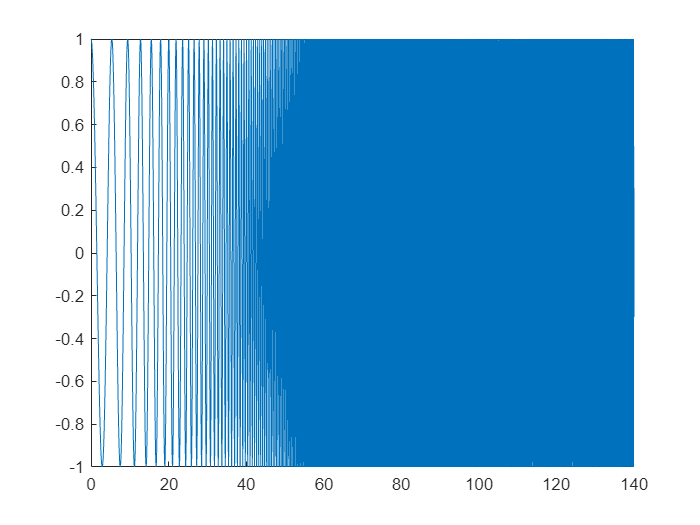


t=(0:st:140)';
w0=1; %rad/s
w1=pi/st; %rad/s     Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts -> valore alto tipo val max dato
control_action = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
figure
plot(t,control_action)

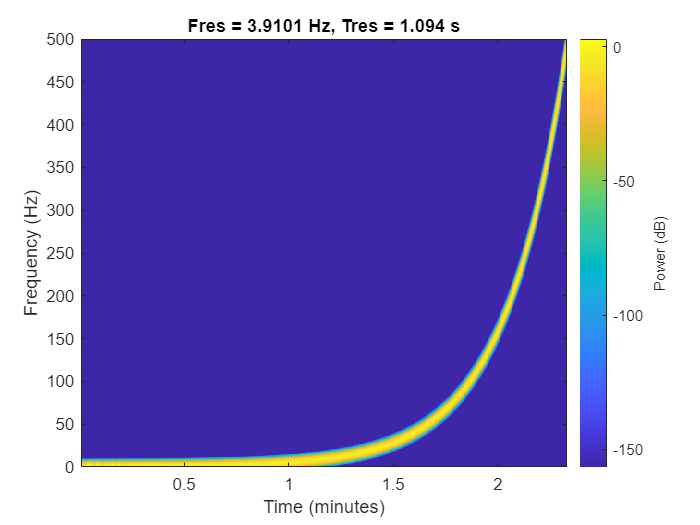

pspectrum(control_action,1/st,'spectrogram');

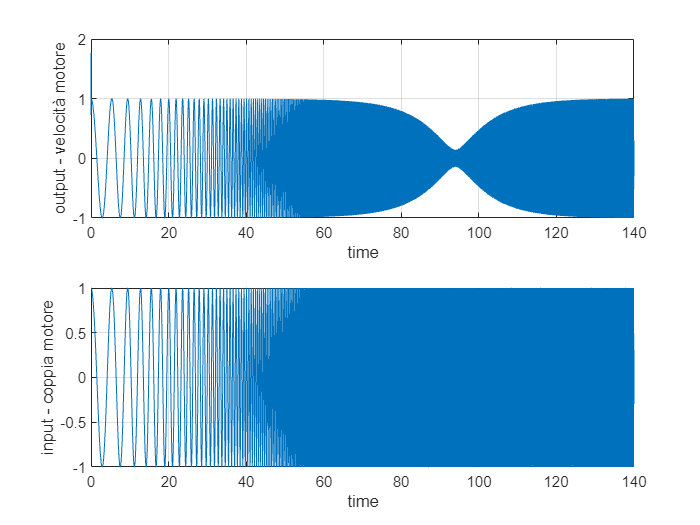


process_output=zeros(length(t),1);
for idx=1:length(t)
    process_output(idx,:)=filtro.Compute(control_action(idx));
end

figure(1)
subplot(2,1,1)
plot(t,process_output(:))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input - coppia motore')
grid on

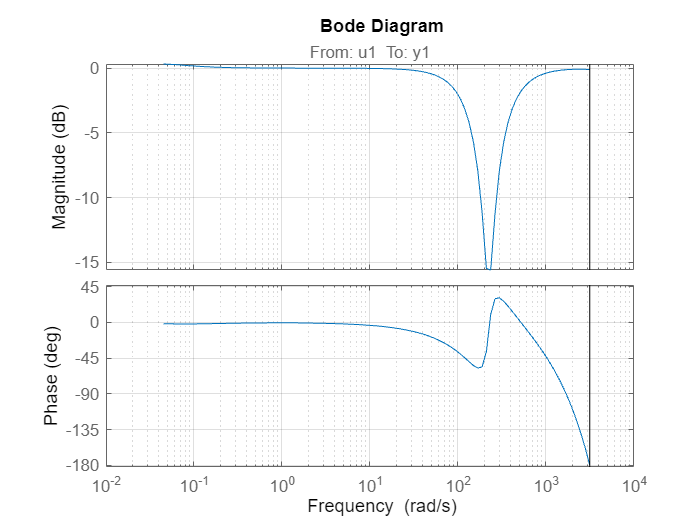


identification=iddata(process_output(:),control_action,st);
freq_resp_ident = spafdr(identification);
figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on